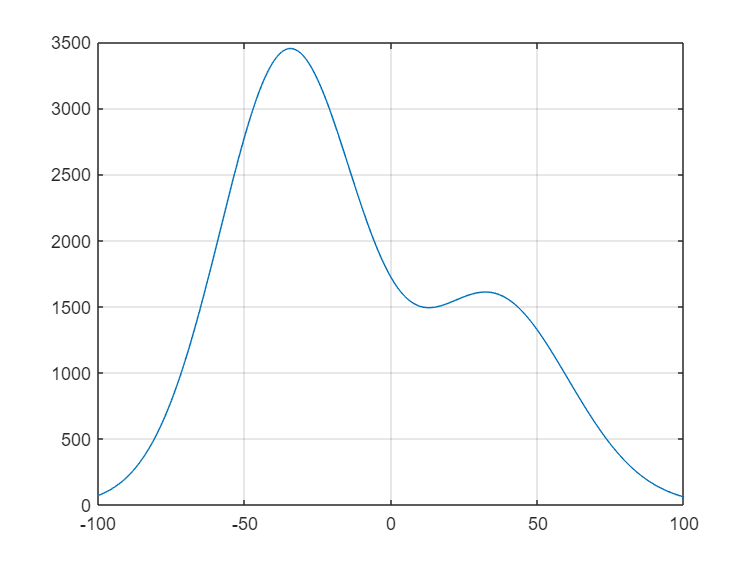

%% Gaussian Signal Generation
ratio1 = 100000;
ratio2 = ratio1*2;
mu1 = 35;
FWHM1 = 60;
sigma1 = FWHM1/(2*sqrt(2*log(2)));
w1 = -100:100;
p1 = -.5 * ((w1 - mu1)/sigma1) .^ 2;
p2 = (sigma1 * sqrt(2*pi));
gauss1 = ratio1*exp(p1) ./ p2;
mu2 = -35;
FWHM2 = 55;
sigma2 = FWHM2/(2*sqrt(2*log(2)));
w2 = -100:100;
p3 = -.5 * ((w2 - mu2)/sigma2) .^ 2;
p4 = (sigma2 * sqrt(2*pi));
gauss2 = ratio2*exp(p3) ./ p4;
plot(w1,gauss1+gauss2);
grid on
hold off

%% Gradient Descent Method
syms t
A = sym('A', [1 6]);
f(A,t)=A(1)*exp(-(t-A(3)^2/(2*A(5)^2))+A(2)*exp(-(t-A(4)))^2/(2*A(6)^2));
learn_rate=0.001;
oldData=[1 1 1 1 1 1];
newData=zeros(1,6);
for i=1:40
    for j=1:6
        g=sum((mean(i)-repmat(f^2,65,1)).^2);
        newData(j)=oldData(j)-eval(subs(diff(g,A(j)),oldData))*learn_rate;
    end
    oldData=newData;
end

Error using evalin
Unrecognized function or variable 'A3'.

Error in sym/eval (line 13)
s = evalin('caller',vectorize(char(x)));